`Implementation ch. 2 Costa's thesis: STOCHASTIC MODELLING OF NEMATODES BEHAVIOUR ACROSS SPECIES (RANDOM WALK)`

`In the following, the mdoel provides the simplest quantitative approach for capturing the observed behavioral statistics of the worm. The only considered elements are the ORIENTATIONAL & TRANSATIONAL dyanmics of the trajectory. `

`The model presents 3 ``independent`` components: `

- `Speed fluctuations`` relaxing to a set point on a few sec time scale`

- `Orientation fluctuations`` with drift `

- `Stochastic switching`` between forward and reverse modes `

`This describes the statistcis of the trajectory. `

`Here the reorientation mechanism are ``excluded`` from the data.  `

`Steps:`

- `Compute statistics for: individual ``isolated`` vs individual in ``collective environemnt`` for different strains and species`

- `Look at parameter space for all individuals `

- `Implement model simulation`

- `    how do parameter statistics compare across isolated and social environment? `

- `    are collective strains/species packed tohgether in the parameter space `

- `    simulation of multiple individuals with trajectory statistcis and no taxi `

- `        can both models generate collective behaviours? `

`Random walk in this model can be decomposed in speed, turning and reversal dynamics.`

`--------------------------------------------------------------------------------------`

`Data ideally required: `

- `One condition for all strains/species and for isolated vs collective environment: food quantity `

- `Isolated individual full body marker (fluorescent) `

- `Group of 40 individuals with 1-3 red full body, and rest heads (fluorescent)`

`--------------------------------------------------------------------------------------`

clear all; close all; clc;
set(0,'DefaultAxesFontSize', 20)

% FLUORESCENT DATA Red 
cd("/Users/erusconi/Documents/Analysis_Data/project_A/data/fluorescence/collective_conditions/skeleton");    
fds = fileDatastore('*.hdf5', 'ReadFcn', @importdata);   % here you can specify which ever file type you prefer 

skelFile = fds.Files;

numFiles = length(skelFile);

% Loop over all files reading them in and plotting them.
for k = 1 : numFiles
    name = sprintf('dataSet_%d', k);   
%     fprintf('Now reading file %s\n', skelFile{k});

    trajData.(name) = h5read(skelFile{k},'/trajectories_data');
    blobFeats.(name) = h5read(skelFile{k},'/blob_features');
    skeleton.(name)= h5read(skelFile{k}, '/skeleton');
end 

- `Video FPS: 9`

- `x,y coordinates units of measure: `

- `conversion factor: `

`Keep only trajectories that are longer then min_length(=50) `

min_length = 50;

for k = 1:numFiles
    name = sprintf('dataSet_%d', k); %
    worm_index_present.(name) = unique(trajData.(name).worm_index_joined); %
    worm_index_kept(1).(name) = []; %
    row_worm_i(1).(name) = [];  %

    for i = 1:size(worm_index_present.(name),1)      % loop through each individual %
        row_worm_i.(name) = [row_worm_i.(name); {find(trajData.(name).worm_index_joined == worm_index_present.(name)(i))}];
        worm_index_kept.(name) = [worm_index_kept.(name); worm_index_present.(name)(i)]; 
        if size(row_worm_i.(name){end},1) < min_length
            row_worm_i.(name){end} = []; 
            worm_index_kept.(name)(end) = [];
        end 
    end 
    row_worm_i.(name) = row_worm_i.(name)(~cellfun('isempty',row_worm_i.(name)));    % delete all cells that are empty 
end 


$$\phi \left(t\right):\textrm{bearing}$$


- `Centrioid direction of movement`

- `This is the angle between direction of movment and x axis`

`Part of the answer is taken from `[`here`](https://it.mathworks.com/matlabcentral/answers/180131-how-can-i-find-the-angle-between-two-vectors-including-directional-information#:~:text=angle%20%3D%20atan2d(x1*y2,*x2%2By1*y2)%3B)

va = [1 0]; 
pOrder = 2;
window = 4;     % with window = 4, we have 2 points to left and 2 to right

for k = 1:numFiles
    name = sprintf('dataSet_%d', k); %
    velocity_centr(1).(name) = [];
    phi(1).(name) = [];

    for i = 1:size(worm_index_kept.(name),1)      % loop through each individual 
        xy_coor.(name){i,1} = [trajData.(name).coord_x(row_worm_i.(name){i}) trajData.(name).coord_y(row_worm_i.(name){i})];
        maxFrame = size(row_worm_i.(name){i},1);
        
        % polynomial fitting for the xy-coord and estimate smoothed velocity 
        for j = 1:2      % loop through x and y 
            for frame = 1 + window/2:maxFrame - window/2  %loop over frames
                dataWin = xy_coor.(name){i}(frame-window/2:frame+window/2,j);    % data in the window considered around the frame to be filtered 
                p = polyfit(1:window+1, dataWin, pOrder);       % polinomial of order pOrder fitted on the data window 
                
                nl = 1+window/2;    % point that is evaluated 
                dataFilt.(name){i,1}(frame,j) = polyval(p,nl);     % velauate the polynomial in the original x value 
                velocity_centr.(name){i,1}(frame,j) = polyval(polyder(p),nl).*9;   % velocity in pixels/seconds
                datadot2Filt.(name){i,1}(frame,j) = polyval(polyder(polyder(p)),nl);
            end
            dataWin = []; 
        end 
    end 
    
    
    for i = 1:size(worm_index_kept.(name),1)
        row_worm_i.(name){i}(1:window/2) = [];
        row_worm_i.(name){i}(end+1-window/2:end) = []; 
        dataFilt.(name){i}(1:window/2,:) = [];
        velocity_centr.(name){i}(1:window/2,:) = [];
    
        % estimate speed 
        speed_centr.(name){i,1} = sqrt(sum((velocity_centr.(name){i}).^2,2));
    
        % estimate angle phi (orientation centrioid vector) 
        for j = 1:size(velocity_centr.(name){i},1)
            vb = velocity_centr.(name){i}(j,:)/speed_centr.(name){i,1}(j); 
            
            phi.(name){i,1}(j,1) = atan2d(vb(1)*va(2)-vb(2)*va(1),vb(1)*va(1)+vb(2)*va(2));
        end 
    end 
end 

`Check Speed estimate vs Speed Smoothed`

%%%%%%%%%%%%% No need to run this, but provides visual example of
%%%%%%%%%%%%% difference between filtered and non filtered data %%%%%%%%%%%%%
% sqrt(sum((vb).^2,2))
% 
% figure 
% plot(speed_centrioid_filt{ind},'r')
% hold on 
% plot(speed_centrioid{ind},'b')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

`Comparison smoothed and non-smoothed data: Plot smoothed trajectory (dataFilt) and smoothed velocity (datadotFilt) for individual ind in red, and non-smoothed data in blue`

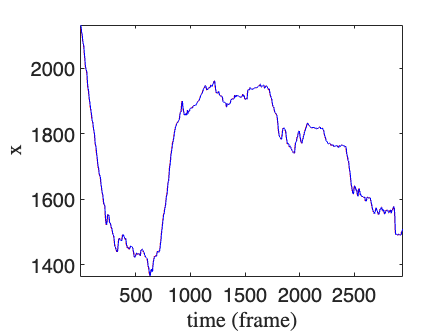

% plot of x-coordinate in time 
name = sprintf('dataSet_%d', 1);
ind = 2;
figure 
plot(dataFilt.(name){ind}(:,1),'r')
hold on 
plot(xy_coor.(name){ind}(:,1),'b')
xlabel('time (frame)','Interpreter','latex')
ylabel('x','Interpreter','latex')
axis tight 

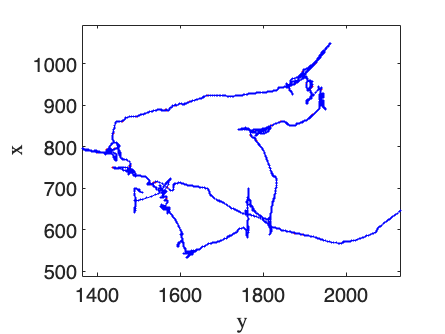


% plot of x,y-coordinate in xy space 
figure 
plot(dataFilt.(name){ind}(:,1),dataFilt.(name){ind}(:,2), 'r.-')
hold on 
plot(xy_coor.(name){ind}(:,1), xy_coor.(name){ind}(:,2),'b.-')
axis equal 
xlabel('y','Interpreter','latex')
ylabel('x','Interpreter','latex')

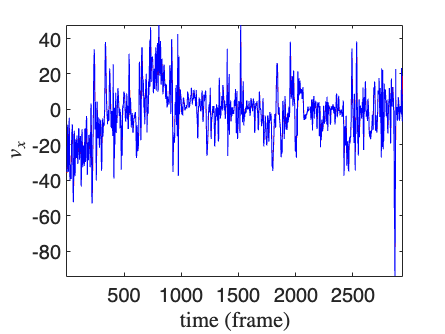


% plot of v_x in time 
figure 
plot(velocity_centr.(name){ind}(:,1),'r')
hold on 
plot(diff(trajData.(name).coord_x(row_worm_i.(name){ind})).*9,'b')
xlabel('time (frame)','Interpreter','latex')
ylabel('$v_x$','Interpreter','latex')
axis tight

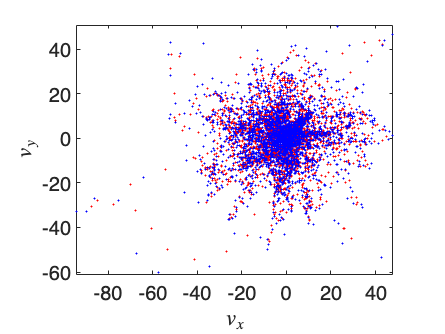


% plot of v_x,v_y in v_x,v_y plane 
figure 
plot(velocity_centr.(name){ind}(:,1),velocity_centr.(name){ind}(:,2), 'r.')
hold on 
plot(diff(trajData.(name).coord_x(row_worm_i.(name){ind})).*9, diff(trajData.(name).coord_y(row_worm_i.(name){ind})).*9,'b.')
axis equal 
xlabel('$v_x$','Interpreter','latex')
ylabel('$v_y$','Interpreter','latex')

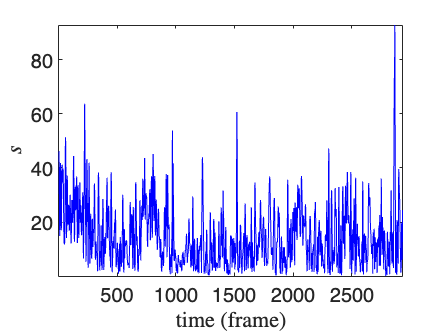


% plot speed in time 
figure 
plot(speed_centr.(name){ind},'b')
xlabel('time (frame)','Interpreter','latex')
ylabel('$s$','Interpreter','latex')
axis tight

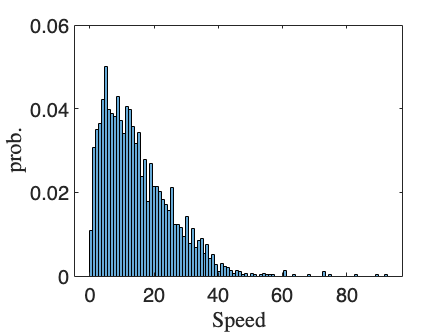

 
% plot histogram speed trajectory ind
figure
histogram(speed_centr.(name){ind},100,'Normalization','probability')
xlabel('Speed','Interpreter','latex')
ylabel('prob.','Interpreter','latex')

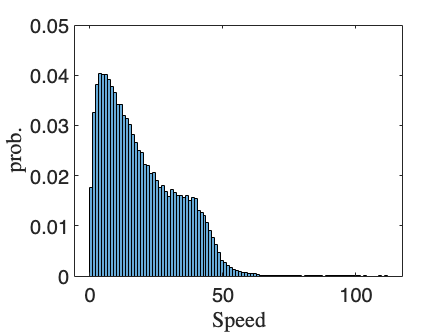

speed_centr_mat = []; 
for k = 1:numFiles
    speed_centr_mat = [speed_centr_mat; cell2mat(speed_centr.(name))];
end 
% plot histogram speed all trajectories
figure
histogram(speed_centr_mat,100,'Normalization','probability')
% xlim([-180, 180]);
% xticks(-180:90:180);
xlabel('Speed','Interpreter','latex')
ylabel('prob.','Interpreter','latex')

`By looking through the smoothed trajectory compared to the original one we can see that the points most affected are the ones during the dwelling part of the trajectory and not the ones during the long distance movement. `

`By looking through the trajectory and seeing when the worm transitions from local dwelling to global exploration we can see that the angles actually coincide! So everything is good! I was expecting the results to look more like Antonio's analysis, but the conditions are very different (food, social) so the time series should be different. It is interesting that the probability distributions aren't actually that different! `

`Check angle distribution for all individuals `

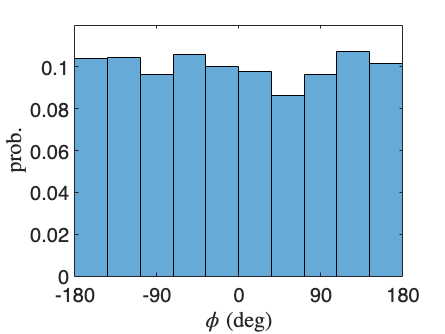

phi_mat = []; 
for k = 1:numFiles
    phi_mat = [phi_mat; cell2mat(phi.(name))];
end 
phi_mat(isnan(phi_mat)) = []; 

figure
histogram(phi_mat,10,'Normalization','probability')
xlim([-180, 180]);
xticks(-180:90:180);
xlabel('$\phi$ (deg)','Interpreter','latex')
ylabel('prob.','Interpreter','latex')

`Plot speed time series for one individual `

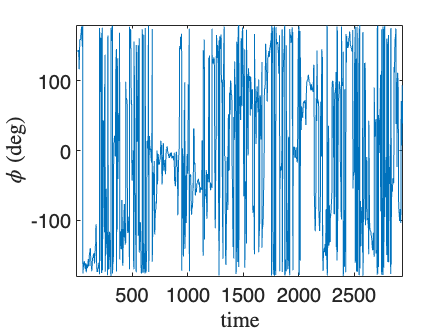

figure 
plot(phi.(name){ind},'-')
xlabel('time','Interpreter','latex')
ylabel('$\phi$ (deg)','Interpreter','latex')
axis tight 

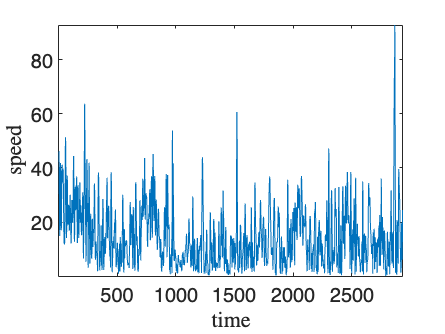


figure 
plot(speed_centr.(name){ind},'-')
xlabel('time','Interpreter','latex')
ylabel('speed','Interpreter','latex')   % fix units
axis tight 

`Expectation: uniform distribution throguh all angles. `


$$\psi \left(t\right):\textrm{orientation}$$


- `to account for head-tail assymetry`

- `Is the vector pointing from centrioid to head `

for k = 1:numFiles
    name = sprintf('dataSet_%d', k); %
    vec_centr_head(1).(name) = [];
    psi(1).(name) = [];

    for i =1:size(worm_index_kept.(name),1)
        head = mean(skeleton.(name)(1:2,1:16,row_worm_i.(name){i,1}),2);
        head = reshape(head,2,size(row_worm_i.(name){i},1))';
        center_Mass = mean(skeleton.(name)(1:2,20:30,row_worm_i.(name){i,1}),2); 
        center_Mass = reshape(center_Mass,2,size(row_worm_i.(name){i},1))';
        vec_centr_head.(name){i,1} = head - center_Mass;
        for j = 1:size(vec_centr_head.(name){i},1)
            vb = vec_centr_head.(name){i}(j,:)/sqrt(sum(vec_centr_head.(name){i}(j,:)).^2);
            psi.(name){i,1}(j,1) = atan2d(vb(1)*va(2)-vb(2)*va(1),vb(1)*va(1)+vb(2)*va(2));
            vb = []; 
        end 
    end 
end 

`Check angle distribution`

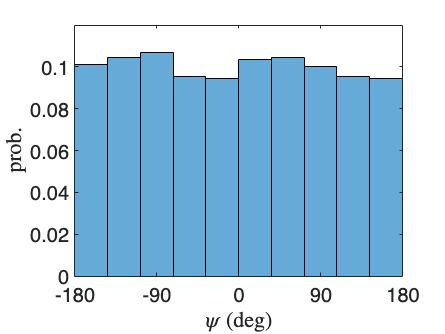

psi_mat = []; 
for k = 1:numFiles
    psi_mat = [psi_mat; cell2mat(phi.(name))];
end 
psi_mat(isnan(psi_mat)) = []; 

figure
histogram(psi_mat,10,'Normalization','probability')
xlim([-180, 180]);
xticks(-180:90:180);
xlabel('$\psi$ (deg)','Interpreter','latex')
ylabel('prob.','Interpreter','latex')

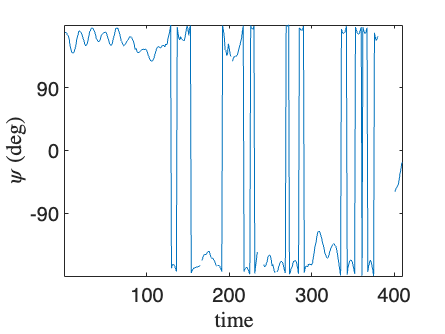


figure 
plot(psi.(name){ind},'-')
ylim([-180, 180]);
yticks(-180:90:180);
xlabel('time','Interpreter','latex')
ylabel('$\psi$ (deg)','Interpreter','latex')
axis tight 

`Expectation: uniform distribution through all angles `


$$\Delta \psi \left(t\right):\textrm{allignment}$$


- `allignemnt of the worm direction of movement (bearing) and the worm body orientation `

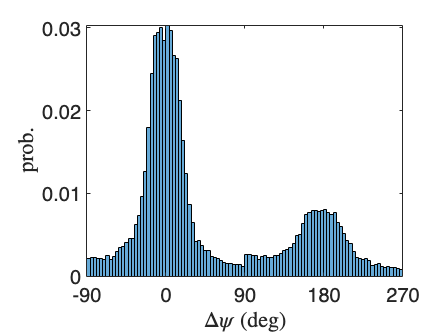

for k = 1:numFiles
    name = sprintf('dataSet_%d', k); %
    delta_psi(1).(name) = [];

    for i =1:size(worm_index_kept.(name),1)
        delta_psi.(name){i,1} = (phi.(name){i} - psi.(name){i});
        for j = 1:size(delta_psi.(name){i},1)   % ask greg if htis makes sense! not sure how to wrap between -90 and 270
            if delta_psi.(name){i}(j) < -90
                delta_psi.(name){i}(j) = abs(delta_psi.(name){i}(j)); 
            end 
            if delta_psi.(name){i}(j) > 270 
                delta_psi.(name){i}(j) = delta_psi.(name){i}(j) -360;
            end 
        end 
    end 
end 

delta_psi_mat = []; 
for k = 1:numFiles
    delta_psi_mat = [delta_psi_mat; cell2mat(delta_psi.(name))];
end 

figure
histogram(delta_psi_mat,100,'Normalization','probability')
xlim([-90, 270]);
xticks(-90:90:270);
xlabel('$\Delta \psi$ (deg)','Interpreter','latex')
ylabel('prob.','Interpreter','latex')
axis tight

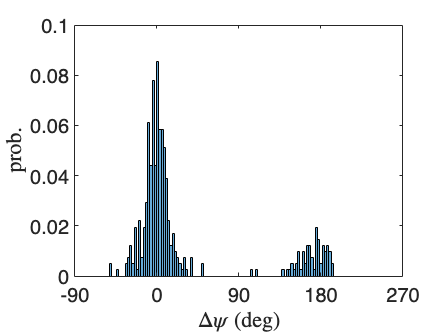


% plot histogram speed trajectory ind
figure
histogram(delta_psi.(name){ind},100,'Normalization','probability')
xlabel('$\Delta \psi$ (deg)','Interpreter','latex')
ylabel('prob.','Interpreter','latex')
xlim([-90, 270]);
xticks(-90:90:270);

`The distribution is as expected with a large peak at 0 indiccating forward crawling and a peak at 180 for backward crawling. The only anomaly that is not in Antonio's results, is a minor peak at 90 and -90. The result is peculiar becuase it would mean that the worm is moving side ways, as if exibiting a rolling behaviour like in drosophila larvas. `

## `MSD`

traj_length = []; 
for k=1:numFiles
    name = sprintf('dataSet_%d', k); %
    traj_length = [traj_length; cellfun('size',row_worm_i.(name),1)];
end 

max_traj_length = max(traj_length); 

for k=1:numFiles
    name = sprintf('dataSet_%d', k); %
    for i=1:size(worm_index_kept.(name),1)%      % loop through all index in data set 
        xy_centrioid_selcted = []; 
        xy_0 = []; 
        
        xy_centrioid_selcted = xy_coor.(name){i,1};
        % VECTOR OF N ENTRIES CONTAINING INITIAL POSITION (MAKES ESTIMATE FASTER) 
        xy_0 = ones(size(xy_centrioid_selcted,1),2).*xy_centrioid_selcted(1,:);     % initial position of trajectory
    
        MSD_terms.(name){i,1} = sum(((xy_centrioid_selcted - xy_0).^2),2); 
    end 
end 

for k=1:numFiles
    name = sprintf('dataSet_%d', k); %
    for i=1:size(worm_index_kept.(name),1)% 
        padd_length = max_traj_length - size(MSD_terms.(name){i},1);
        MSD_terms.(name){i} = [MSD_terms.(name){i}; NaN(padd_length,1)];
    end   
end

MSD_terms_concat(1).(name) = [];
MSD_concat_all = [];
for k=1:numFiles
    for i =1:size(worm_index_kept.(name),1)
        MSD_terms_concat.(name) = [MSD_terms_concat.(name), MSD_terms.(name){i}];
    end
    MSD_concat_all = [MSD_concat_all, MSD_terms_concat.(name)];
end 
MSD_mean = nanmean(MSD_concat_all,2); 

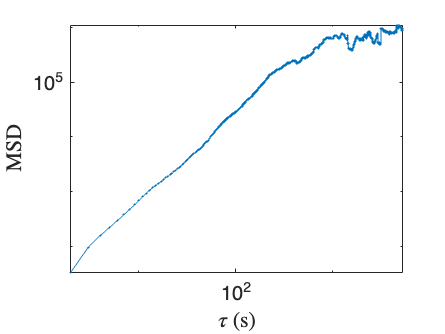

% PLOT MSD ALL 
figure 
loglog(MSD_mean,'.-')
xlabel('$\tau$ (s)','Interpreter','latex')
ylabel('MSD','Interpreter','latex')
axis tight

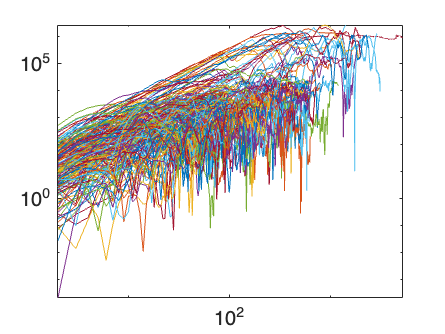


% PLOT MSD 
figure 
loglog(MSD_concat_all(:,500:745),'-')
axis tight

`TILL HERE EVRYTHING IS CONVERTED `

`Data cleaning: `

`The resulting `$\Delta \psi \left(t\right)$` looks particularly noisy. When looking at the ``time dynamics`` it seems like the worm continuesly swithes between forward and backward crawling. Have to smooth the trajectory. First check which of the two vectors is contributing to the noise mostly. `

% figure 
% plot(delta_psi{ind},'-')
% ylabel('$\Delta \psi$','Interpreter','latex')
% xlabel('time','Interpreter','latex')
% ylim([-90, 270]);
% yticks(-90:90:270);
% % axis tight 
% 
% figure 
% plot(cos(delta_psi{ind}),'.')
% ylabel('$cos( \Delta \psi)$','Interpreter','latex')
% xlabel('time','Interpreter','latex')
% ylim([-1, 1]);
% yticks(-1:1:1);
% % axis tight 
% 
% figure 
% histogram(cos(delta_psi{ind}),100)
% 
% figure 
% plot(trajData.coord_x(row_worm_i{ind}), trajData.coord_y(row_worm_i{ind}),'.-')
% ylabel('y','Interpreter','latex')
% xlabel('x','Interpreter','latex')
% title('Trajectory','Interpreter','latex')
% axis equal

`It seems like the center of mass is really good actually. Not too much noise. I might want to compute the speed over two frames and averaging, but it seems minor. `

`Check how the vector from the centioid to the head is `

% figure 
% quiver(trajData.coord_x(row_worm_i{ind}),trajData.coord_y(row_worm_i{ind}),velocity_centr{ind}(:,1),velocity_centr{ind}(:,2))
% ylabel('y','Interpreter','latex')
% xlabel('x','Interpreter','latex')
% title('$v_{cm}$','Interpreter','latex')
% axis equal 

`The centrioid to head looks like it's not too noisy. Not sure what theproblem is! `

`Plot the arrows color coded based on if moving forward or backward. `

% % histogram delta_psi on trajectory number ind 
% figure
% histogram(delta_psi{ind},100)
% ylabel('Prob.','Interpreter','latex')
% xlabel('$\Delta \psi$','Interpreter','latex')
% title('Distribution individual','Interpreter','latex')
% 
% % find forward and backward moevement (discretely defined) 
% forward_row = find((delta_psi{ind} > -90) & (delta_psi{ind} < 90));
% backward_row = find((delta_psi{ind} < -90) | (delta_psi{ind} > 90));
% 
% % plot of vector centrioid to head color coded based on forward/backward
% figure
% quiver(trajData.coord_x(row_worm_i{ind}(forward_row)),trajData.coord_y(row_worm_i{ind}(forward_row)),vec_centr_head{ind}(forward_row,1),vec_centr_head{ind}(forward_row,2),0,'blue');
% hold on 
% quiver(trajData.coord_x(row_worm_i{ind}(backward_row)),trajData.coord_y(row_worm_i{ind}(backward_row)),vec_centr_head{ind}(backward_row,1),vec_centr_head{ind}(backward_row,2),0,'red');
% axis equal 
% ylabel('y','Interpreter','latex')
% xlabel('x','Interpreter','latex')

`Compute the change in `$\phi \left(t\right)$, $\psi \left(t\right)$ and $\Delta \psi \left(t\right)$ `angle and look at the amplitude of the changes`

% for i=1:size(phi,1)
%     change_phi{i} = abs(diff(phi{i}));
%     change_psi{i} = abs(diff(psi{i}));
%     change_delta_psi{i} = diff(delta_psi{i});
%     for j =1:size(change_delta_psi{i},1)   % ask greg if htis makes sense! not sure how to wrap between -90 and 270
%         if change_delta_psi{i}(j) < -90
%             change_delta_psi{i}(j) = abs(change_delta_psi{i}(j)); 
%         end 
%         if change_delta_psi{i}(j) > 270 
%             change_delta_psi{i}(j) = change_delta_psi{i}(j) -360;
%         end 
%     end 
% end 
% 
% figure 
% plot(change_phi{ind},'-')
% ylabel('$\delta \phi$','Interpreter','latex')
% xlabel('time','Interpreter','latex')
% 
% figure 
% plot(change_psi{ind},'-')
% ylabel('$\delta \psi$','Interpreter','latex')
% xlabel('time','Interpreter','latex')

`Large changes in the Vh (interestingly enough) are always either 360 or 180. The 180 indicates misscategorization of the head probably, while 360 is simply no change at all. I hate angles!!!! `

% 
% figure 
% plot(change_delta_psi{ind},'-')
% ylabel('$\delta \Delta \psi$','Interpreter','latex')
% xlabel('time','Interpreter','latex')

`So it looks like the center of mass velocity is the more noisy component. `

`Exploration of ``amplitude and time scale fluctuations`` in speed, `$\phi \left(t\right)$`, `$\psi \left(t\right)$` and `$\Delta \psi \left(t\right)$` time series: Autocovariance `

% for i = 1:size(worm_index_kept,1)
%     [autoCov_speed{i,1} lags1{i,1}] = xcov(speed_centr{i},'coeff');
%     [autoCov_phi{i,1} lags2{i,1}] = xcov(phi{i},'coeff'); 
%     [autoCov_psi{i,1} lags3{i,1}] = xcov(psi{i}(~isnan(psi{i})),'coeff');
%     [autoCov_delta_psi{i,1} lags4{i,1}] = xcov(delta_psi{i}(~isnan(delta_psi{i})),'coeff');
% end
% 
% figure 
% subplot(2,2,1)
% plot(lags1{ind}', autoCov_speed{ind},'.-')
% ylabel('$C_{s}$','Interpreter','latex')
% xlabel('lag','Interpreter','latex')
% axis tight
% 
% subplot(2,2,2)
% plot(lags2{ind}', autoCov_phi{ind},'.-')
% ylabel('$C_{\phi}$','Interpreter','latex')
% xlabel('lag','Interpreter','latex')
% axis tight
% 
% subplot(2,2,3)
% plot(lags3{ind}', autoCov_psi{ind},'.-')
% ylabel('$C_{\psi}$','Interpreter','latex')
% xlabel('lag','Interpreter','latex')
% axis tight
% 
% subplot(2,2,4)
% plot(lags4{ind}', autoCov_delta_psi{ind},'.-')
% ylabel('$C_{\delta \psi}$','Interpreter','latex')
% xlabel('lag','Interpreter','latex')
% axis tight

`Compute autocovariance plot averaging over all trajectories `

% speed_centrioid_filt_mat = []; 
% longest_trajectory_length = max(cellfun('size',speed_centr,1));    % find longest cell for padding all others 
% for i=1:size(worm_index_kept,1)
%     padd_length = longest_trajectory_length - size(speed_centr{i},1);
% 
%     speed_centrioid_filt_term{i,1} = [speed_centr{i}; NaN(padd_length,1)]'; 
%     phi_term{i,1} = [phi{i}; NaN(padd_length,1)]';
%     psi_term{i,1} = [psi{i}; NaN(padd_length,1)]';
%     delta_psi_term{i,1} = [delta_psi{i}; NaN(padd_length,1)]'; 
% end 
% speed_centrioid_filt_mat = cell2mat(speed_centrioid_filt_term)';
% speed_mean = mean(speed_centrioid_filt_mat,2,'omitnan');
% [autoCov_speed_mean lags_mean_speed] = xcov(speed_mean,'coeff');
% 
% phi_mat = cell2mat(phi_term)'; 
% phi_mean =  mean(phi_mat,2,'omitnan');
% [autoCov_phi_mean lags_mean_phi] = xcov(phi_mean,'coeff');
% 
% psi_mat = cell2mat(psi_term)';
% psi_mean = mean(psi_mat,2,'omitnan');
% [autoCov_psi_mean lags_mean_psi] = xcov(psi_mean(~isnan(psi_mean)),'coeff');
% 
% delta_psi_mat = cell2mat(delta_psi_term)';
% delta_psi_mean = mean(delta_psi_mat,2,'omitnan');
% [autoCov_delta_psi_mean lags_mean_delta_psi] = xcov(delta_psi_mean(~isnan(delta_psi_mean)),'coeff');
% 
% 
% 
% figure 
% subplot(2,2,1)
% plot(lags_mean_speed(~isnan(autoCov_speed_mean)), autoCov_speed_mean,'.-')
% ylabel('$C_{s}$','Interpreter','latex')
% xlabel('lag','Interpreter','latex')
% axis tight
% 
% subplot(2,2,2)
% plot(lags_mean_phi(~isnan(autoCov_phi_mean)), autoCov_phi_mean,'.-')
% ylabel('$C_{\phi}$','Interpreter','latex')
% xlabel('lag','Interpreter','latex')
% axis tight
% 
% subplot(2,2,3)
% plot(lags_mean_psi(~isnan(autoCov_psi_mean)), autoCov_psi_mean,'.-')
% ylabel('$C_{\psi}$','Interpreter','latex')
% xlabel('lag','Interpreter','latex')
% axis tight
% 
% subplot(2,2,4)
% plot(lags_mean_delta_psi(~isnan(autoCov_delta_psi_mean)), autoCov_delta_psi_mean,'.-')
% ylabel('$C_{\Delta \psi}$','Interpreter','latex')
% xlabel('lag','Interpreter','latex')
% axis tight

`I think the calculations are correct but should look through them again. Have to check how ANtonio finds the timescale of fluctuations. The plot 2.3B is the MSAD (Mean Square Angular Displacement) which is something I still have to estimate. `

`The plot for the speed autocorrelation function `

% autoCov_speed_mean_Positive = autoCov_speed_mean(find(lags_mean_speed >= 0));
% x = [0:size(~isnan(autoCov_speed_mean_Positive),1)-1]; 
% figure 
% plot(x, autoCov_speed_mean_Positive,'.-')
% ylabel('$C_{s}$','Interpreter','latex')
% xlabel('lag','Interpreter','latex')
% axis tight

`Compute the autocovariance excluding points of transitions between forward and reverse runs `

% % for i =1:size(worm_index_kept,1)
% %     % identify points of transitions using delta_psi
% %     % find forward and backward moevement (discretely defined) 
% %     forward_row = find((delta_psi{ind} > -90) & (delta_psi{ind} < 90));
% %     backward_row = find((delta_psi{ind} < -90) | (delta_psi{ind} > 90));
% %     
% %     speed_centrioid_filt_no_transitions{i,1} = 

`Compute autocovarinace on speed, ``excluding points of transitions`` between forward and backward movement. `

`Establish points of transition `

% 

### `Repeat analysis on number of strains/species`

`Load strains/species data `

% % clear all; close all; clc;
% cd '/Users/erusconi/Desktop/EmmaStuff/BriggsaeAndTropicalis /Day 1 /Skeleton'
% fds = fileDatastore('*.hdf5', 'ReadFcn', @importdata);   % here you can specify which ever file type you prefer 
% 
% skelFile = fds.Files;
% 
% numFiles = length(skelFile);
% 
% 
% % Loop over all files reading them in and plotting them.
% for k = 1 : numFiles
%     name = sprintf('dataSet_%d', k);   
%     fprintf('Now reading file %s\n', skelFile{k});
% 
%     trajData_struc.(name) = h5read(skelFile{k},'/trajectories_data');
%     blobFeats_struc.(name) = h5read(skelFile{k},'/blob_features');
%     skeleton_struc.(name)= h5read(skelFile{k}, '/skeleton');
% end 
% 
% cd '/Users/erusconi/Desktop/EmmaStuff/BriggsaeAndTropicalis /Day 1 /FeaturesN'
% fds = fileDatastore('*.hdf5', 'ReadFcn', @importdata);   % here you can specify which ever file type you prefer 
% 
% featuresFile = fds.Files;
% 
% numFiles = length(featuresFile);
% 
% % Loop over all files reading them in and plotting them.
% for k = 1 : numFiles
%     name = sprintf('dataSet_%d', k);    
%     fprintf('Now reading file %s\n', featuresFile{k});
% 
%     time_series.(name)= h5read(featuresFile{k}, '/timeseries_data');
% end  
% cd('..')
% cd('/Users/erusconi/Desktop/EmmaStuff/BriggsaeAndTropicalis ')

`Video FPS: 25.`

`Identify all rows corresponding to different strains/species `

`index_strain_i is a cell where each cell entrance contains the rows corresponding to the strain`

% number_strains = 7; 
% index_strain_i = cell(7,1);
% 
% % 818
% letter_ind = ['A', 'B', 'C', 'D']';
% 
% groups_incl = ['1', '2', '3','4'];
% name = sprintf('dataSet_%d', 2);
% timeSeries2_cell = struct2cell(time_series.(name)); 
% for i = 1:size(letter_ind,1) % loop through the letters 
%     letter = letter_ind(i);
%     for k=1:size(groups_incl,1)
%         index_strain_i{i,1} = [index_strain_i{i,1}; find((timeSeries2_cell{3}(1,:) == letter) & (timeSeries2_cell{3}(2,:) == groups_incl(k)))']; 
%     end 
% end 
% 
% % 816
% letter_ind = ['E','F','G']';
% name = sprintf('dataSet_%d', 1);
% timeSeries1_cell = struct2cell(time_series.(name)); 
% for i = 1:size(letter_ind,1) % loop through the letters 
%     letter = letter_ind(i);
%     j = i+4;
%     for k=1:size(groups_incl,1)
%         index_strain_i{j,1} = [index_strain_i{i,1}; find((timeSeries1_cell{3}(1,:) == letter) & (timeSeries1_cell{3}(2,:) == groups_incl(k)))'];
%     end 
% end 

`Find the rows corresponding to the individuals part of each strain `

`Individuals_in_strains is a cell in which each cell entrance contains the worm_index values correspinding to the individuals part of that strain and specie `

% for i=1:size(index_strain_i,1) % loop through the strains 
% 
%     if i < 5
%         name = sprintf('dataSet_%d', 2);
%     else 
%         name = sprintf('dataSet_%d', 1);
%     end 
%     
%     individuals_in_strains{i,1} = unique(trajData_struc.(name).worm_index_joined(index_strain_i{i})); 
% end 

`Genrate cell structure containing each inidivudal rows per strain `

% for i=1:size(individuals_in_strains,1)      % loop through strains 
% 
%     if i < 5
%         name = sprintf('dataSet_%d', 2);
%     else 
%         name = sprintf('dataSet_%d', 1);
%     end 
% 
%     for j=1:size(individuals_in_strains{i},1)       % loop through worm index in the strain
%         row_worm_i_strain{i,1}{j,1} = find(trajData_struc.(name).worm_index_joined == individuals_in_strains{i}(j));
%     end 
% end 


$$\phi \left(t\right):\textrm{bearing}$$


% % phi_strain = cell(size(worm_index_kept,1),1);
% % velocity_centrioid_strain = cell(size(worm_index_kept,1),1);
% va = [1 0]; 
% 
% for i=1:size(row_worm_i_strain,1)      % loop through strains 
% 
%     if i < 5
%         name = sprintf('dataSet_%d', 2);
%     else 
%         name = sprintf('dataSet_%d', 1);
%     end 
% 
%     for j=1:size(row_worm_i_strain{i},1)
%         term = [diff(trajData_struc.(name).coord_x(row_worm_i_strain{i}{j})) diff(trajData_struc.(name).coord_y(row_worm_i_strain{i}{j}))];
%         speed_centrioid_strain{i,1}{j} = sqrt(sum((term).^2,2));
%         velocity_centrioid_strain{i,1}{j} = term./speed_centrioid_strain{i}{j};
%         for k = 1:size(velocity_centrioid_strain{i}{j},1)
%             vb = velocity_centrioid_strain{i}{j}(k,:); 
%             
%             phi_strain{i,1}{j,1}(k,1) = atan2d(vb(1)*va(2)-vb(2)*va(1),vb(1)*va(1)+vb(2)*va(2));
%             vb = []; 
%         end 
%         term = []; 
%     end 
% end 

% phi_strain_mat = [];
% for i = 1:size(phi_strain,1)
%     phi_strain_mat = [phi_strain_mat; cell2mat(phi_strain{i})];
% end 

`Plot all distributions in one to check that things make sense `

% figure
% histogram(phi_strain_mat,10,'Normalization','probability')
% xlim([-180, 180]);
% xticks(-180:90:180);
% xlabel('$\phi$ (deg)','Interpreter','latex')
% ylabel('prob.','Interpreter','latex')

`The distribution is comparable to the on eobtained for the npr1 data set. Seems to have worked correctly.`

`Plot all strains distributions in same plot `

% phi_strain_divided = {[];[];[];[];[];[];[]}; 
% for i = 1:size(phi_strain,1)
%     phi_strain_divided{i} = [phi_strain_divided{i}; cell2mat(phi_strain{i})];
% end 
% 
% figure 
% for i=1:size(phi_strain,1)
%     subplot(4,2,i)
%     histogram(phi_strain_divided{i},10,'Normalization','probability')
%     hold on 
% end 
% xlabel('$\phi$ (deg)','Interpreter','latex')
% ylabel('prob.','Interpreter','latex')

All distributions show a uniform distrubution with minor deviationc for sstrains 2 and 3. This is probably due to the limited amount of data I have. 


$$\psi \left(t\right):\textrm{orientation}$$


% va = [1 0]; 
% 
% for i=1:size(row_worm_i_strain,1)      % loop through strains 
% 
%     if i < 5
%         name = sprintf('dataSet_%d', 2);
%     else 
%         name = sprintf('dataSet_%d', 1);
%     end
% 
% 
%     for j = 1:size(row_worm_i_strain{i},1)     % loop through individuals in strain
%         head = mean(skeleton_struc.(name)(1:2,1:16,row_worm_i_strain{i}{j}),2);
%         head = reshape(head,2,size(row_worm_i_strain{i}{j},1))';
%         vec_centrioid_head_strain{i,1}{j} = head - [trajData_struc.(name).coord_x(row_worm_i_strain{i,1}{j}) trajData_struc.(name).coord_y(row_worm_i_strain{i,1}{j})];
%         for r = 1:size(vec_centrioid_head_strain{i}{j},1)       % loop through time
%             vb = vec_centrioid_head_strain{i}{j}(r,:)/sqrt(sum(vec_centrioid_head_strain{i}{j}(r,:)).^2);
%             psi_strain{i,1}{j,1}(r,1) = atan2d(vb(1)*va(2)-vb(2)*va(1),vb(1)*va(1)+vb(2)*va(2));
%             vb = []; 
%         end 
%     end 
%     head =[];
% end 
% 

% psi_strain_mat = [];
% for i = 1:size(psi_strain,1)
%     psi_strain_mat = [psi_strain_mat; cell2mat(psi_strain{i})];
% end 
% 
% figure
% histogram(psi_strain_mat,100,'Normalization','probability')
% xlim([-180, 180]);
% xticks(-180:90:180);
% xlabel('$\psi$ (deg)','Interpreter','latex')
% ylabel('prob.','Interpreter','latex')
% 

`Plot all strains distributions in same plot `

% psi_strain_divided = {[];[];[];[];[];[];[]}; 
% for i = 1:size(psi_strain,1)
%     psi_strain_divided{i} = [psi_strain_divided{i}; cell2mat(psi_strain{i})];
% end 
% 
% figure 
% for i=1:size(psi_strain,1)
%     subplot(4,2,i)
%     histogram(psi_strain_divided{i},100,'Normalization','probability')
%     xlim([-270, 270]);
%     xticks(-270:90:270);
%     hold on 
% end 
% xlabel('$\phi$ (deg)','Interpreter','latex')
% ylabel('prob.','Interpreter','latex')


$$\Delta \psi \left(t\right):\textrm{allignment}$$


% for i=1:size(row_worm_i_strain,1)      % loop through strains 
% 
%     if i < 5
%         name = sprintf('dataSet_%d', 2);
%     else 
%         name = sprintf('dataSet_%d', 1);
%     end
% 
% 
%     for j = 1:size(row_worm_i_strain{i},1)     % loop through individuals in strain
%         delta_psi_strain{i,1}{j,1} = phi_strain{i,1}{j,1} - psi_strain{i}{j}(1:end-1);
%     end 
% end 

% delta_psi_strain_mat = [];
% for i = 1:size(delta_psi_strain,1)
%     delta_psi_strain_mat = [delta_psi_strain_mat; cell2mat(delta_psi_strain{i})];
% end 
% 
% 
% figure
% histogram(delta_psi_strain_mat,100,'Normalization','probability')
% xlim([-270, 270]);
% xticks(-270:90:270);
% xlabel('$\psi$ (deg)','Interpreter','latex')
% ylabel('prob.','Interpreter','latex')

% strain_name_1 = sprintf('C. elegans strain 1 (n=%d)', size(index_strain_i{1},1));
% strain_name_2 = sprintf('C. tropicalis strain 1 (n=%d)', size(index_strain_i{2},1));
% strain_name_3 = sprintf('C. briggsae strain 1 (n=%d)', size(index_strain_i{3},1));
% strain_name_4 = sprintf('C. tropicalis strain 2 (n=%d)', size(index_strain_i{4},1));
% strain_name_5 = sprintf('C. elegans strain 2 (n=%d)', size(index_strain_i{5},1));
% strain_name_6 = sprintf('C. briggsae strain 2 (n=%d)', size(index_strain_i{6},1));
% strain_name_7 = sprintf('C. elegans strain 3 (n=%d)', size(index_strain_i{7},1));
% STRAIN_NAME = { strain_name_1, strain_name_2, strain_name_3, strain_name_4, strain_name_5, strain_name_6, strain_name_7};
% 
% 
% delta_psi_strain_divided = {[];[];[];[];[];[];[]}; 
% for i = 1:size(delta_psi_strain,1)
%     delta_psi_strain_divided{i} = [delta_psi_strain_divided{i}; cell2mat(delta_psi_strain{i})];
% end 
% 
% figure 
% for i=1:size(delta_psi_strain,1)
%     subplot(4,2,i)
%     histogram(delta_psi_strain_divided{i},100,'Normalization','probability')
%     xlim([-270, 270]);
%     xticks(-270:90:270);
%     ylim([0 0.15])
%     hold on 
%     title(STRAIN_NAME{i})
% end 
% xlabel('$\Delta \psi$ (deg)','Interpreter','latex')
% ylabel('prob.','Interpreter','latex')
% 
% figure 
% plot(cos(delta_psi_strain{5}{1}),'.')

`Next analysis: implement analysis conducted on firefly trajectories to this data!`

`Caracterize and categorize the trjectories based on a few variables. What does it tell me about the data? `